**Definition du systeme**

Nous avons un système avec trois fréquences de coupure. Définissons G(s) la fonction de transfert du  moteur, F(s) la fonction de transfert du filtre et C(s) la fonction de transfert du correcteur.

clear all;
close all; 
clc;
s=tf('s');

G(s):

L=0.002

L = 0.0020

R=1

R = 1

t1= L/R

t1 = 0.0020

Kg=1/R

Kg = 1

Km=24

Km = 24

G=Kg*Km/(1+t1*s)

G =
 
      24
  -----------
  0.002 s + 1
 
Continuous-time transfer function.



F(s)

t2= 7.43*10^-5

t2 = 7.4300e-05

t3= 4.84*10^-6

t3 = 4.8400e-06

K_capteur=0.10416

K_capteur = 0.1042

Kf=1.457

Kf = 1.4570

F=K_capteur*Kf/((1+t2*s)*(1+t3*s))

F =
 
              0.1518
  -------------------------------
  3.596e-10 s^2 + 7.914e-05 s + 1
 
Continuous-time transfer function.



C(s) [ti est la constante d'integration et K le gain du PI]

K=1

K = 1

ti=1 %choix de ti???????

ti = 1

C=K*(t1*s+1)/(t1*s)

C =
 
  0.002 s + 1
  -----------
    0.002 s
 
Continuous-time transfer function.



Tracé du diagramme de Bode en boucle ouverte afin de determiner K pour avoir une fréquence de coupure entre 300 et 500Hz


%bode(C*G*F)
K=0.1

K = 0.1000

C=K*(t1*s+1)/(t1*s)

C =
 
  0.0002 s + 0.1
  --------------
     0.002 s
 
Continuous-time transfer function.



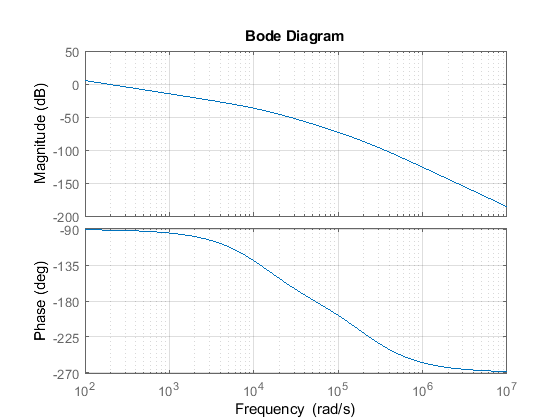


bode(C*G*F)
grid on

Il ne reste qu'a faire la simulation en boucle fermée de notre système corrigé. 